# Experiment 4.2

## Name: Tim Roche

## Objectives

To evaluate the effect of additional poles and zeros upon the time response of second-order systems.  

### Minimum Required Software Packages

MATLAB, Simulink, and the Control System Toolbox.

## Prelab

### Problem 1

#### 1.a.

*Given the transfer function *$G(s) = \frac{25}{s^2 + 4s + 25}$*, evaluate the percent overshoot, settling time, peak time, and rise time. Also, plot the poles.  *

**Answer:**

*Finding *$\omega_n, \zeta$


$$w_n = 5$$
 

$2\zeta\omega_n = 4$ -> $2\zeta = \frac{4}{5}$ -> $\zeta = \frac{2}{5}$

*Finding *$\omega_d$


$$\omega_d = w_n\sqrt{(1-\zeta^2)}$$



$$\omega_d = (5)\sqrt{(1-(\frac{2}{5})^2)} = \sqrt{21}$$


*Finding Ts and Tp*


$$T_s = \frac{4}{\zeta\omega_n} = \frac{4}{(\frac{2}{5})5} = 2$$



$$T_p = \frac{\pi}{w_d} = \frac{\pi}{\sqrt{21}} = 0.686$$


*Finding Tr*


$$\omega_n T_r = 1.76\zeta^3 - 0.417\zeta^2 + 1.039\zeta + 1$$



$$(5) T_r = 1.76(\frac{2}{3})^3 - 0.417(\frac{2}{3})^2 + 1.039(\frac{2}{3}) + 1$$



$$T_r = 0.326
$$


*Finding %OS*


$$\%OS = e^{\frac{-\zeta\pi}{\sqrt{1 - \zeta^2}}}(100)$$



$$\%OS = e^{\frac{-\frac{2}{5}\pi}{\sqrt{1 - \frac{2}{5}^2}}}(100) = 25.38\%$$


*Poles*


$$-2 \pm j\sqrt{21}$$


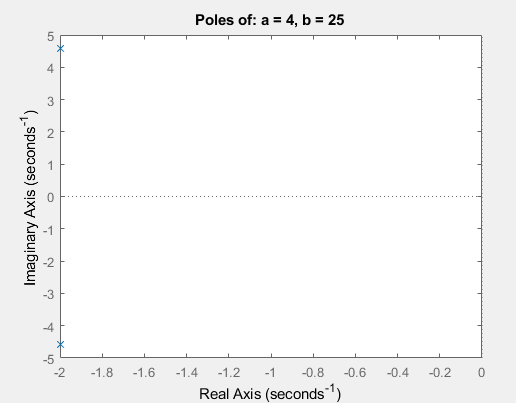

#### 1.b.

*Add a pole at -200 to the system of **Prelab 1a**. Estimate whether the transient response in **Prelab 1a** will be appreciably affected.*

**Answer:**


$$\frac{25}{(s^2 + 4s + 25)(s+200)}$$


**Second Order Pole: **$-2 \pm j\sqrt{21}$

**Additional Pole: **-200

-200 is at least five times greater than -2. Therefore, the additional pole will not have a signifigant effect on the system and can be ignored. 

#### 1.c.

*Repeat **Prelab 1b** with the pole successively placed at -20, -10, and -2.*

**Answer:**

### Problem 2

*A zero is added to the system of Prelab 1a at -200 and then moved to -50, -20, -10, -5, and -2. List the values of zero location in order of the ****greatest**** to the ****least**** effect upon the pure second-order transient response.*

**Answer:**

[-2, -5, -10, -20, -50, -200]

*greatest* <-----------> *least*

Large magnitude zeros (large $a$) will mostly effect the DC gain of the steady state response. However, small magnitude zeros will mostly effect the transient response and the amount of overshoot as the derivative of the original transfer function is dominate ($sC(s)$). This can be seen in the equation below. 


$$(s+a)C(s) = sC(s) + aC(s)$$


Since this question only asks about the transient response, small values of zeros will have a greater effect than larger values of zeros.

### Problem 3

*Given the transfer function *$G(s) = \frac{(25b/a)(s+1)}{(s+b)(s^2 + 4s + 25)}$*, let *$a=3$* and *$b=$*3.01, 3.1, 3.3, 3.5, and 4.0. Which values of *$b$* will have minimal effect upon the pure second-order transient response?*

**Answer:**

Partial fractions and Laplace transforms were taken in Wolfram Alpha. 

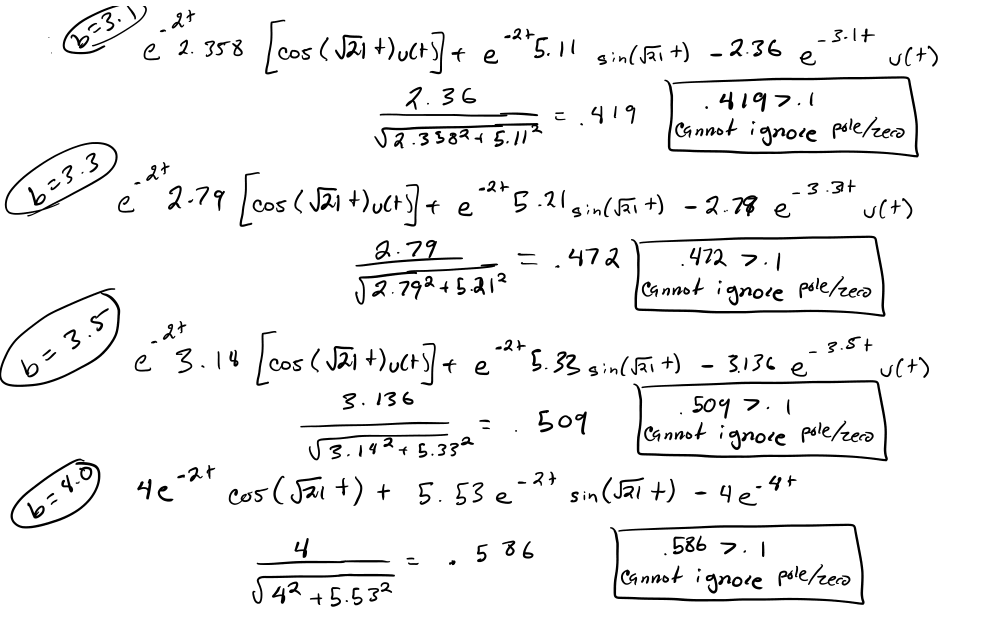

### Problem 4

*Given the transfer function *$G(s) = \frac{(2500b/a)(s+a)}{(s+b)(s^2 + 4s + 25)}$*, let *$a=30$* and *$b=$*30.01, 30.1, 30.5, 31, 35, and 40. Which values of *$b$* will have minimal effect upon the pure second-order transient response?*

**Answer:**

Partial fractions and Laplace transforms were taken in Wolfram Alpha. 

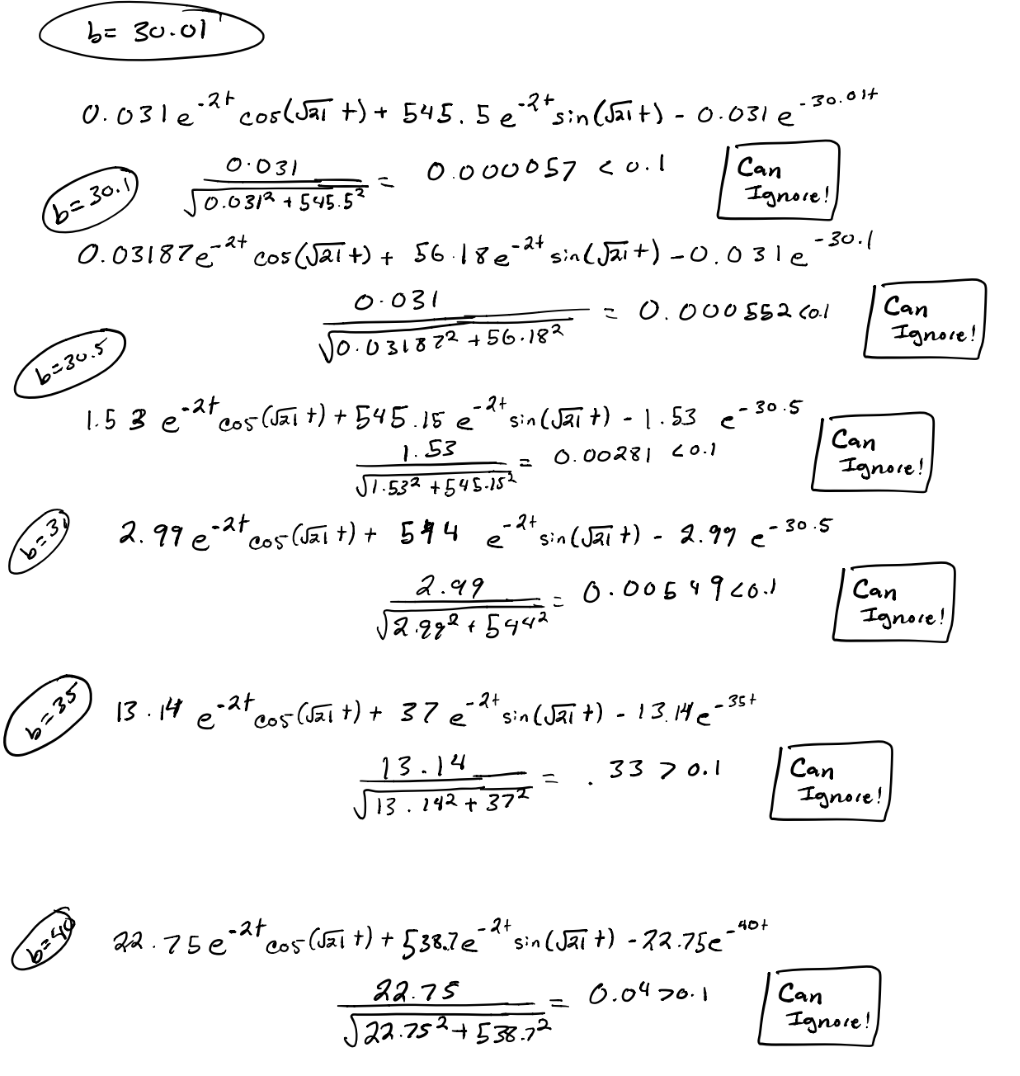

## Lab

### Problem 1

*Using Simulink, add a pole to the second-order system of **Prelab 1a* *and plot the step responses of the system when the higher order pole is ****nonexistent****, at  -200, -20, -10,  and -2. Make your plots on a single graph, using the Simulink LTI Viewer. Normalize all plots to a steady-state value of unity. Record percent overshoot, settling time, peak time, and rise time for each response.*

*____________________________*

$G(s) = \frac{25}{s^2 + 4s + 25}$*,*

*____________________________*

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

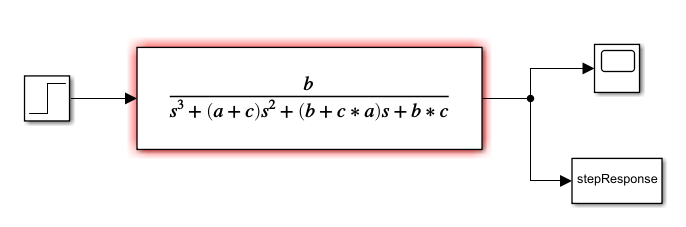

a = 4;
b = 25;
c_vals = [200, 20, 10, 2];
figure(1)

%Plotting for no poles
simOut = sim('question.slx','ReturnWorkspaceOutputs','on');
disp("No Poles")

No Poles


stepinfo( simOut.question.Data, simOut.question.Time)

ans = struct with fields:
        RiseTime: 0.2927
    SettlingTime: 1.6819
     SettlingMin: 0.9006
     SettlingMax: 1.2538
       Overshoot: 25.3826
      Undershoot: 0
            Peak: 1.2538
        PeakTime: 0.6860



hold on
plot(simOut.question.Time, simOut.question.Data/simOut.question.Data(length(simOut.question.Data)))
%Plotting with poles
for i=1:length(c_vals)
    c = c_vals(i);
    sim('Ex4_2_P1.slx');
    normData = stepResponse.data./stepResponse.data(length(stepResponse.Data));
    plot(stepResponse.time, normData, "linewidth", 2);
    disp(c_vals(i))
    stepinfo(stepResponse.data, stepResponse.time)
    stepResponses{i} = stepResponse;
end

   200



ans = struct with fields:
        RiseTime: 0.2928
    SettlingTime: 1.6869
     SettlingMin: 0.0045
     SettlingMax: 0.0063
       Overshoot: 25.3746
      Undershoot: 0
            Peak: 0.0063
        PeakTime: 0.6910


    20



ans = struct with fields:
        RiseTime: 0.3062
    SettlingTime: 1.7325
     SettlingMin: 0.0450
     SettlingMax: 0.0623
       Overshoot: 24.5136
      Undershoot: 0
            Peak: 0.0623
        PeakTime: 0.7400


    10



ans = struct with fields:
        RiseTime: 0.3356
    SettlingTime: 1.7787
     SettlingMin: 0.0900
     SettlingMax: 0.1219
       Overshoot: 21.9297
      Undershoot: 0
            Peak: 0.1219
        PeakTime: 0.7990


     2



ans = struct with fields:
        RiseTime: 0.7495
    SettlingTime: 2.0911
     SettlingMin: 0.4502
     SettlingMax: 0.5000
       Overshoot: 0
      Undershoot: 0
            Peak: 0.5000
        PeakTime: 10


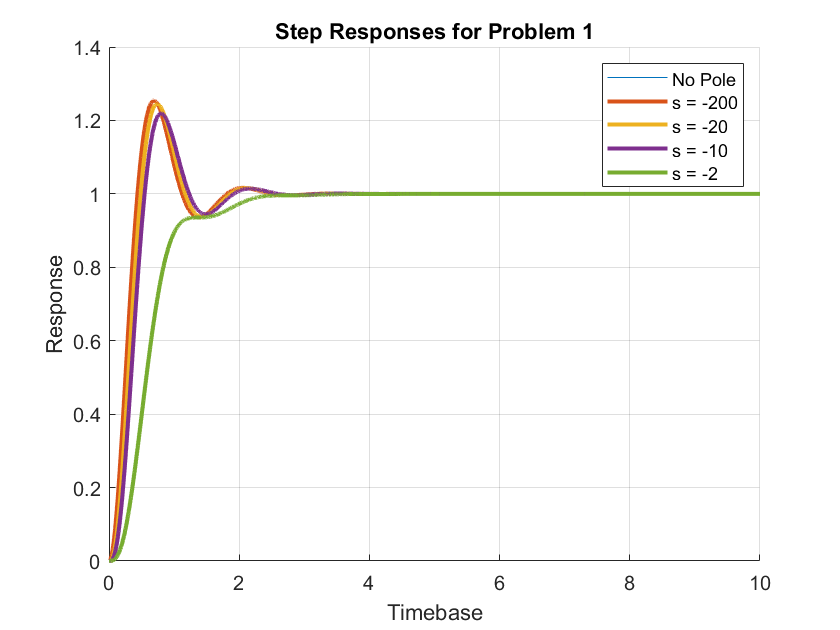

hold off
title("Step Responses for Problem 1")
xlabel("Timebase")
ylabel("Response")
legend(["No Pole" "s = -200" "s = -20" "s = -10" "s = -2"])
grid on

### Problem 2

*Using Simulink, add a zero to the second-order system of **Prelab 1a* *and plot the step responses of the system when the zero is nonexistent, at  -200, -50, -20, -10, -5, and -2. Make your plots on a single graph, using the Simulink LTI Viewer. Normalize all plots to a steady-state value of unity. Record percent overshoot, settling time, peak time, and rise time for each response.  *

*___________*

$G(s) = \frac{25}{s^2 + 4s + 25}$*,*

*___________*

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

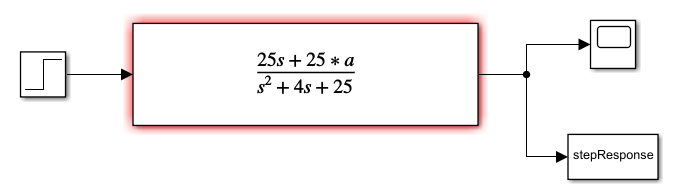

a_vect = [200, 50, 20, 10, 5, 2];
figure(2);

%Plotting for no zeros
simOut = sim('question.slx','ReturnWorkspaceOutputs','on');
disp("No Zeros")

No Zeros


stepinfo( simOut.question.Data, simOut.question.Time)

ans = struct with fields:
        RiseTime: 0.2927
    SettlingTime: 1.6819
     SettlingMin: 0.9006
     SettlingMax: 1.2538
       Overshoot: 25.3826
      Undershoot: 0
            Peak: 1.2538
        PeakTime: 0.6860



hold on
plot(simOut.question.Time, simOut.question.Data/simOut.question.Data(length(simOut.question.Data)))
%Plotting with zeros
for i=1:length(a_vect)
    a = a_vect(i);
    sim('Ex4_2_P2.slx');
    
    disp("zero at -"+a);
    stepinfo(stepResponse.data, stepResponse.time)
    stepResponses{i} = stepResponse;
    
    normData = stepResponse.data./stepResponse.data(length(stepResponse.Data));
    plot(stepResponse.time, normData, "linewidth", 2);
end

zero at -200


ans = struct with fields:
        RiseTime: 0.2926
    SettlingTime: 1.6768
     SettlingMin: 180.1352
     SettlingMax: 250.7813
       Overshoot: 25.3906
      Undershoot: 0
            Peak: 250.7813
        PeakTime: 0.6810


zero at -50


ans = struct with fields:
        RiseTime: 0.2905
    SettlingTime: 1.6617
     SettlingMin: 45.0979
     SettlingMax: 62.7582
       Overshoot: 25.5164
      Undershoot: 0
            Peak: 62.7582
        PeakTime: 0.6650


zero at -20


ans = struct with fields:
        RiseTime: 0.2789
    SettlingTime: 1.6311
     SettlingMin: 18.0121
     SettlingMax: 25.2565
       Overshoot: 26.2826
      Undershoot: 0
            Peak: 25.2565
        PeakTime: 0.6310


zero at -10


ans = struct with fields:
        RiseTime: 0.2444
    SettlingTime: 1.5830
     SettlingMin: 9.0049
     SettlingMax: 12.9366
       Overshoot: 29.3661
      Undershoot: 0
            Peak: 12.9366
        PeakTime: 0.5720


zero at -5


ans = struct with fields:
        RiseTime: 0.1697
    SettlingTime: 2.0105
     SettlingMin: 4.4561
     SettlingMax: 7.1427
       Overshoot: 42.8542
      Undershoot: 0
            Peak: 7.1427
        PeakTime: 0.4690


zero at -2


ans = struct with fields:
        RiseTime: 0.0715
    SettlingTime: 2.0246
     SettlingMin: 1.4140
     SettlingMax: 4.3088
       Overshoot: 115.4378
      Undershoot: 0
            Peak: 4.3088
        PeakTime: 0.3430


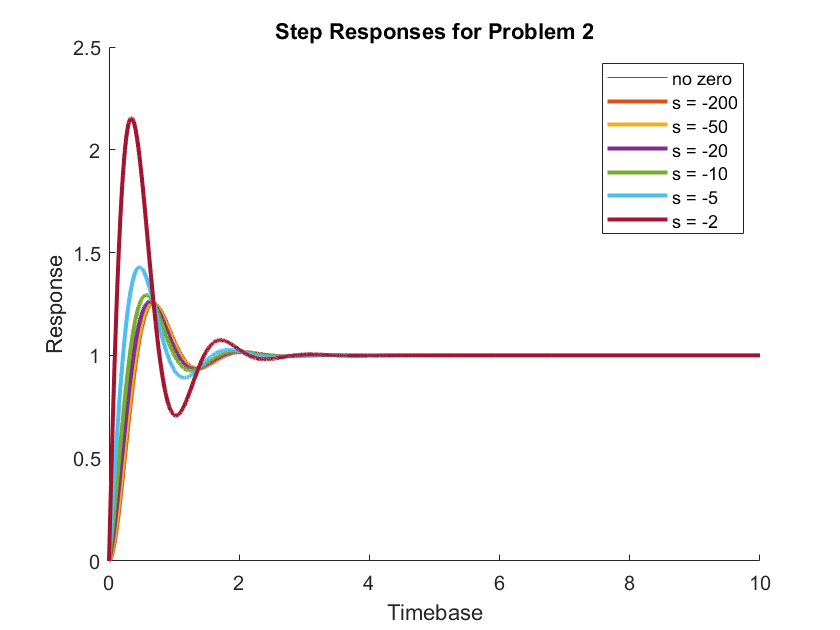

hold off

title("Step Responses for Problem 2")
xlabel("Timebase")
ylabel("Response")
legend(["No zero" "s = -200" "s = -50" "s = -20" "s = -10" "s = -5" "s = -2"])

### Problem 3

________________

$G(s) = \frac{(25b/a)(s+1)}{(s+b)(s^2 + 4s + 25)}$*, let *$a=3$

________________

*Using Simulink and the transfer function of **Prelab 3** with a = 3, plot the step responses of the system when the value of b is 3, 3.01, 3.1, 3.3, 3.5, and 4.0. Make your plots on a single graph using the Simulink LTI Viewer. Record percent overshoot, settling time, peak time, and rise time for each response.*

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

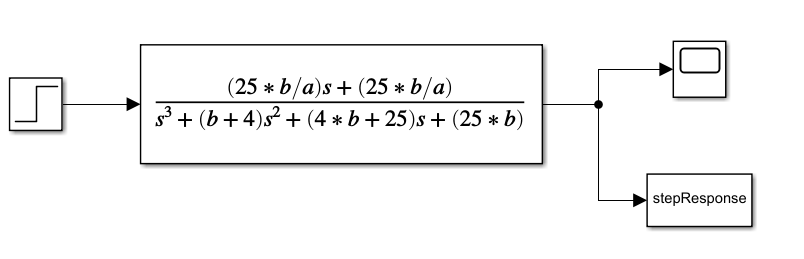

a = 3;
b_vect = [3, 3.01, 3.1, 3.3, 3.5, 4.0];
figure(3);
hold on
for i=1:length(b_vect)
    b = b_vect(i);
    sim('Ex4_2_P3.slx');
    normData = stepResponse.data./stepResponse.data(length(stepResponse.Data));
    plot(stepResponse.time, normData, "linewidth", 2);
    disp("pole at -"+b);
    stepinfo(stepResponse.data, stepResponse.time)
    stepResponses{i} = stepResponse;
end

pole at -3


ans = struct with fields:
        RiseTime: 0.1390
    SettlingTime: 2.2415
     SettlingMin: 0.2714
     SettlingMax: 0.7785
       Overshoot: 133.5519
      Undershoot: 0
            Peak: 0.7785
        PeakTime: 0.5380


pole at -3.01


ans = struct with fields:
        RiseTime: 0.1388
    SettlingTime: 2.2409
     SettlingMin: 0.2710
     SettlingMax: 0.7796
       Overshoot: 133.8891
      Undershoot: 0
            Peak: 0.7796
        PeakTime: 0.5380


pole at -3.1


ans = struct with fields:
        RiseTime: 0.1365
    SettlingTime: 2.2360
     SettlingMin: 0.2674
     SettlingMax: 0.7896
       Overshoot: 136.8667
      Undershoot: 0
            Peak: 0.7896
        PeakTime: 0.5340


pole at -3.3


ans = struct with fields:
        RiseTime: 0.1319
    SettlingTime: 2.2265
     SettlingMin: 0.2595
     SettlingMax: 0.8104
       Overshoot: 143.1326
      Undershoot: 0
            Peak: 0.8104
        PeakTime: 0.5260


pole at -3.5


ans = struct with fields:
        RiseTime: 0.1277
    SettlingTime: 2.2184
     SettlingMin: 0.2519
     SettlingMax: 0.8298
       Overshoot: 148.9527
      Undershoot: 0
            Peak: 0.8298
        PeakTime: 0.5180


pole at -4


ans = struct with fields:
        RiseTime: 0.1190
    SettlingTime: 2.2018
     SettlingMin: 0.2344
     SettlingMax: 0.8727
       Overshoot: 161.8191
      Undershoot: 0
            Peak: 0.8727
        PeakTime: 0.5020


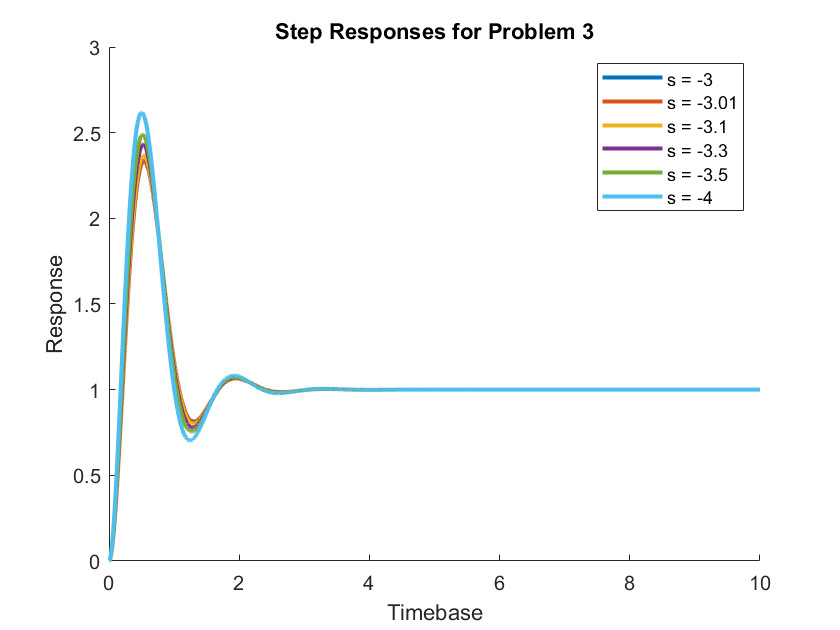

hold off

title("Step Responses for Problem 3")
xlabel("Timebase")
ylabel("Response")
legend("s = -"+b_vect)

### Problem 4

*Using Simulink and the transfer function of **Prelab 4** with *$a = 30$*, plot the step responses of the system when the value of  b is 30, 30.01, 30.1, 30.5, 31, 35, and 40. Make your plots on a single graph, using the Simulink LTI Viewer. Record percent overshoot, settling time, peak time, and rise time for each response.*

*____________________*

$G(s) = \frac{(2500b/a)(s+a)}{(s+b)(s^2 + 4s + 25)}$*, let *$a=30$

*____________________*

*For your Simulink, please provide a screenshot that **clearly** shows the system.*

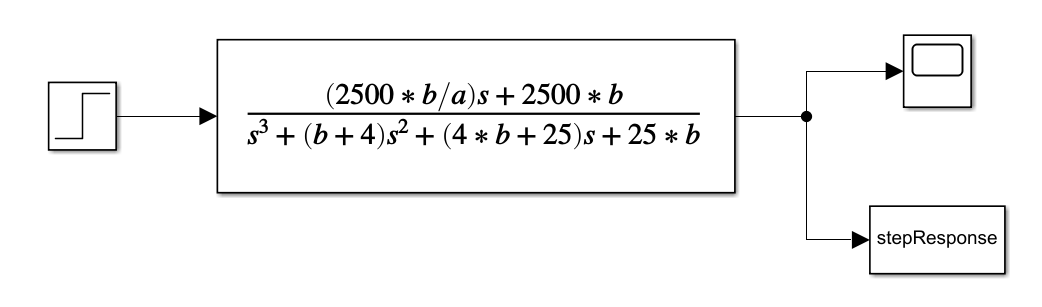

a = 30;
b_vect = [30, 30.01, 30.1, 30.5, 31, 35, 40];
figure(4);

hold on
for i=1:length(b_vect)
    b = b_vect(i);
    sim('Ex4_2_P4.slx');
    normData = stepResponse.data./stepResponse.data(length(stepResponse.Data));
    plot(stepResponse.time, normData, "linewidth", 2);
    disp("pole at -"+b);
    stepinfo(stepResponse.data, stepResponse.time)
    stepResponses{i} = stepResponse;
end

pole at -30


ans = struct with fields:
        RiseTime: 0.2927
    SettlingTime: 1.6819
     SettlingMin: 90.0586
     SettlingMax: 125.3826
       Overshoot: 25.3826
      Undershoot: 0
            Peak: 125.3826
        PeakTime: 0.6860


pole at -30.01


ans = struct with fields:
        RiseTime: 0.2927
    SettlingTime: 1.6819
     SettlingMin: 90.0615
     SettlingMax: 125.3829
       Overshoot: 25.3829
      Undershoot: 0
            Peak: 125.3829
        PeakTime: 0.6860


pole at -30.1


ans = struct with fields:
        RiseTime: 0.2927
    SettlingTime: 1.6818
     SettlingMin: 90.0879
     SettlingMax: 125.3852
       Overshoot: 25.3852
      Undershoot: 0
            Peak: 125.3852
        PeakTime: 0.6850


pole at -30.5


ans = struct with fields:
        RiseTime: 0.2925
    SettlingTime: 1.6813
     SettlingMin: 90.2031
     SettlingMax: 125.3955
       Overshoot: 25.3955
      Undershoot: 0
            Peak: 125.3955
        PeakTime: 0.6850


pole at -31


ans = struct with fields:
        RiseTime: 0.2923
    SettlingTime: 1.6808
     SettlingMin: 90.0979
     SettlingMax: 125.4076
       Overshoot: 25.4076
      Undershoot: 0
            Peak: 125.4076
        PeakTime: 0.6840


pole at -35


ans = struct with fields:
        RiseTime: 0.2910
    SettlingTime: 1.6770
     SettlingMin: 90.0891
     SettlingMax: 125.4868
       Overshoot: 25.4868
      Undershoot: 0
            Peak: 125.4868
        PeakTime: 0.6800


pole at -40


ans = struct with fields:
        RiseTime: 0.2899
    SettlingTime: 1.6734
     SettlingMin: 90.0436
     SettlingMax: 125.5538
       Overshoot: 25.5538
      Undershoot: 0
            Peak: 125.5538
        PeakTime: 0.6760


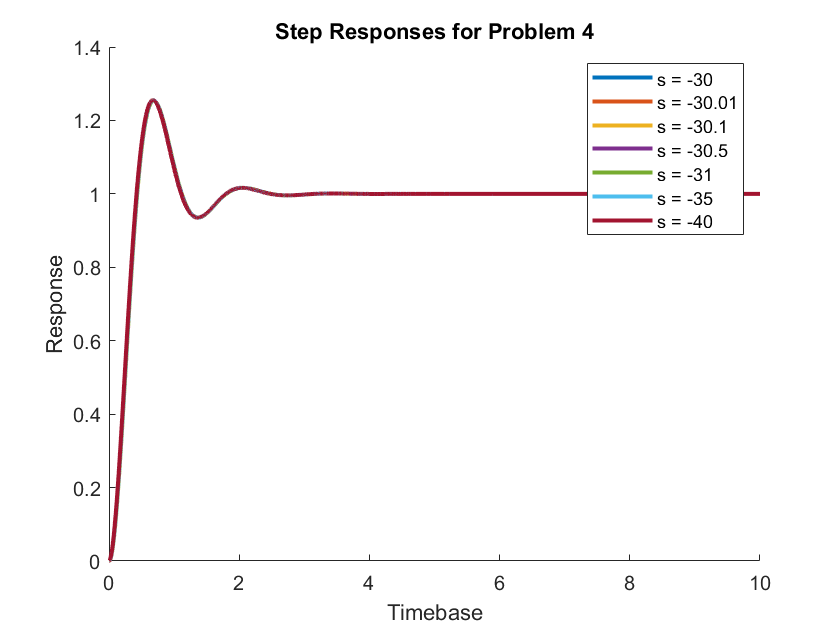

hold off

title("Step Responses for Problem 4")
xlabel("Timebase")
ylabel("Response")
legend("s = -"+b_vect)

## Postlab

### Problem 1

*Discuss the effect upon the transient response of the proximity of a higher-order pole to the dominant second-order pole pair. * 

The closer the real component of the third pole is in magnitude to the two dominate poles, the more the effect the third pole will have on peak time, settling time and precent overshoot this third pole will have. If this third pole is in the left hand plane, this a close third pole leads to a slower response, delayed rise times and settle times. These effects are due to the signifigant time constant on the third pole which effects the system for a long enough period of time to effect key parameters and not just die off near immediately.  

However, as the third poles moves farther and farther out towards infinity, the time constant of this third pole continues to decrease, resulting it having less and less effect on key parameters of the system. The system begins to behave more and more just like a 2nd order system. In fact, if this pole is 5x farther away from the two dominate poles, it is safe to just completely ignore it and treat the problem simply as a second order system.

### Problem 2

*Discuss the effect upon the transient response of the proximity of a zero to the dominant second-order pole pair. Explore the relationship between the length of the vector from the zero to the dominant pole and the zero’s effect upon the pure second-order step response.*

As the vector from the dominate pole to the zero becomes larger and larger, the zeros effect becomes only a scaling of the response of the system without the zero present ($aC(s)$). This is why in the results presented, all graphs where normalized. This was to account for this DC gain for systems with large zeros and to normalize them so that the different zero locations are easier to compare. 

If the zero is close to the two dominate poles, then the scaling effect will be smaller and the dirivitive of the original system will dominate ($sC(s)$), this leads to additional overshoot, when the zero is negative. From experimental data, it was also seen that the larger in magnitude the zero, the smaller the rise time, settling time, and peak time. In the event that the zero is positive, then the derivative would start out negative, leading to a non-minumum phase system where the system starts by doing to opposite of the disired action at first before correcting. 

### Problem 3

*Discuss the effect of pole-zero cancellation upon the transient response of a dominant second-order pole pair. Allude to how close the canceling pole and zero should be and the relationships of (1) the distance between them and (2) the distance between the zero and the dominant second-order poles.  *

As a zero gets closer and closer to the location of the pole, the coefficient of this third pole becomes smaller and smaller. If the zero becomes exactly the same value as the pole, then the pole and zero cancel out and coefficient of this term in the time domain is 0. There is no set rule on how small the coefficient of the third pole needs to be in order to be able to assume that the system behaves close enough to a second order system. However, a good rule of thumb, according to the textbook, is that the magnitude of the real component of the dominate poles must have a coefficient that is at least two orders of magnitude larger than the coefficient of the third pole. However, in class and in the lab above, the magnitude of the coefficent of the third pole must be only one order of magnitude larger than the two dominate poles.